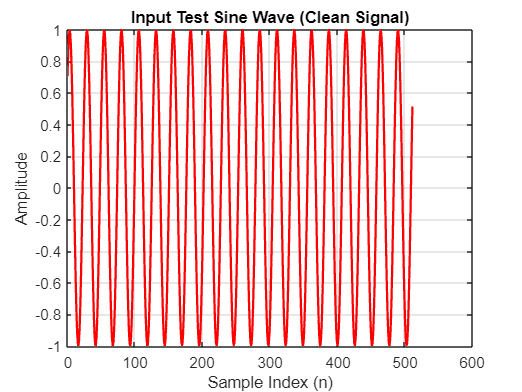

% CA CFAR Algorithmus
clear all;
close all;
clc;

% CA CFAR Parameters (adjusted)
N  = 512;     % Sample Size
NG = 2;       % Guard Cells (increased)
NR = 12;      % Reference Cells (increased)
PFA = 1e-2;   % Probability of False Alarm (relaxed)
MIN_MAG = 1e-4;
alpha = NR * (PFA^(-1/NR) - 1);

% Signal Parameters
A0 = 1;
fs = 256;
ks1 = 20.0;
phase1 = -pi/4;

f1 = fs/N * ks1;
n = 0:(N-1);

% Generate clean sine wave (input test signal)
x = A0 * cos(2*pi*f1/fs*n + phase1);

% Add noise to generate noisy signal for FFT and CFAR
A0eff = A0/sqrt(2);
noise = A0eff * randn(N,1);
xnoise = x + noise';

% === Plot Figure 1: Input Test Sine Wave ONLY ===
figure(1)
plot(n, x, 'r', 'LineWidth', 1.5);
xlabel('Sample Index (n)');
ylabel('Amplitude');
title('Input Test Sine Wave (Clean Signal)');
grid on;

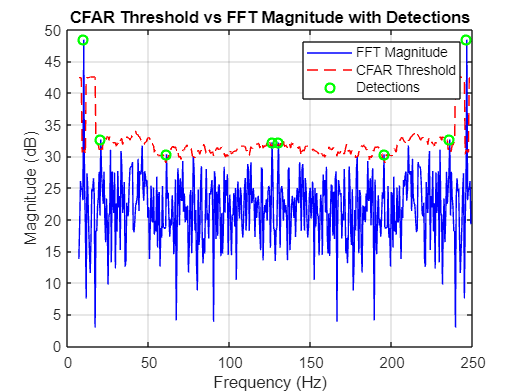


% === Spectral Computation of noisy signal ===
X = fft(xnoise, N);
f = linspace(0, fs, N);

% Interleaved buffer like in C
fft_buffer = zeros(2*N, 1);
fft_buffer(1:2:end) = real(X); % real parts
fft_buffer(2:2:end) = imag(X); % imag parts

% Initialize CFAR outputs
cfar_output = zeros(N, 1);
thresholds = zeros(N, 1);
magnitude = zeros(N, 1);

% CFAR processing loop - corrected (NO scaling)
for i = (NR + NG + 1):(N - (NR + NG))
    noise_sum = 0;

    % Leading reference cells
    for j = (i - NR - NG):(i - NG - 1)
        re = fft_buffer(2*j - 1);
        im = fft_buffer(2*j);
        noise_sum = noise_sum + re^2 + im^2;
    end

    % Lagging reference cells
    for j = (i + NG + 1):(i + NG + NR)
        re = fft_buffer(2*j - 1);
        im = fft_buffer(2*j);
        noise_sum = noise_sum + re^2 + im^2;
    end

    noise_avg = noise_sum / (2*NR);
    threshold = alpha * noise_avg;
    thresholds(i) = threshold;

    % CUT (cell under test)
    re = fft_buffer(2*i - 1);
    im = fft_buffer(2*i);
    mag = re^2 + im^2;
    magnitude(i) = mag;

    if mag > threshold && mag > MIN_MAG
        cfar_output(i) = 1;
    end
end

% === Plot Figure 2: FFT magnitude + CFAR threshold + detections ===
figure(2)
plot(f, 10*log10(magnitude), 'b'); hold on;
plot(f, 10*log10(thresholds), 'r--');

% Mark detections in green circles
detected_indices = find(cfar_output);
plot(f(detected_indices), 10*log10(magnitude(detected_indices)), 'go', ...
    'LineWidth', 1.5, 'MarkerSize', 6);

xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('CFAR Threshold vs FFT Magnitude with Detections');
legend('FFT Magnitude', 'CFAR Threshold', 'Detections');
grid on;


% Display number of detected targets
num_targets = sum(cfar_output);
fprintf('Number of targets detected: %d\n', num_targets);

Number of targets detected: 8
